clear; clc;
theta2 = sym('theta_2');
theta3 = sym("theta_3");
theta4 = sym('theta_4');

l2 = 67.5; AB = 55; l5 = 47.5; l3 = 105;
O2x = 0; O2y = 0;
O5x = 30; O5y = -120;
l4 = 120;
ground = sqrt(O5x^2+O5y^2);

OB = sqrt(l2^2 + AB^2)

OB = 87.0704

An = atand(AB/l2);

Ax = O2x + l2*cos(theta2);
Ay = O2y + l2*sin(theta2);
Cx = O5x + l5*cos(theta4);
Cy = O5y + l5*sin(theta4);

%figure()

%theta_to_plot = deg2rad(0:5:360);

%hold on
%plot(O2x,O2y,"k^")
%plot(O5x,O5y,"k^")

%plot(subs(Ax,theta_to_plot), subs(Ay,theta_to_plot))
%plot(subs(Cx,theta_to_plot), subs(Cy,theta_to_plot))
%grid on

%hold off
%axis equal

eq1 = Ax == Cx + l3*cos(theta3);
eq2 = Ay == Cy + l3*sin(theta3);

sol = solve([eq1 eq2],[theta2 theta3]);


theta2_sol = sol.theta_2(2);
theta3_sol = sol.theta_3(2);

Bx = O2x + OB*cos(theta2_sol-deg2rad(An));
By = O2y + OB*sin(theta2_sol-deg2rad(An));
Dx = O5x; 
Dy = O2y + OB*cos(-theta2_sol+deg2rad(90+An)) - sqrt(l4^2 - (OB*sin(-theta2_sol+deg2rad(90+An))^2));

Axnew = subs(Ax,theta2,theta2_sol);
Aynew = subs(Ay,theta2,theta2_sol);
symvar([Axnew Aynew]);

h_link5 = @(t) plot([O5x subs(Cx,t)], ...
                    [O5y subs(Cy,t)],"g-")

h_link5 = function_handle with value:
    @(t)plot([O5x,subs(Cx,t)],[O5y,subs(Cy,t)],"g-")



h_link2 = @(t) plot([O2x subs(Axnew,t) subs(Bx,t) O2x], ...
                    [O2y subs(Aynew,t) subs(By,t) O2y],"b-")

h_link2 = function_handle with value:
    @(t)plot([O2x,subs(Axnew,t),subs(Bx,t),O2x],[O2y,subs(Aynew,t),subs(By,t),O2y],"b-")



h_link3 = @(t) plot([subs(Cx,t) subs(Axnew,t)], ...
                    [subs(Cy,t) subs(Aynew,t)], "r-")

h_link3 = function_handle with value:
    @(t)plot([subs(Cx,t),subs(Axnew,t)],[subs(Cy,t),subs(Aynew,t)],"r-")



h_link4 = @(t) plot([subs(Bx,t) subs(Dx,t)], ...
                    [subs(By,t) subs(Dy,t)], "k-")

h_link4 = function_handle with value:
    @(t)plot([subs(Bx,t),subs(Dx,t)],[subs(By,t),subs(Dy,t)],"k-")


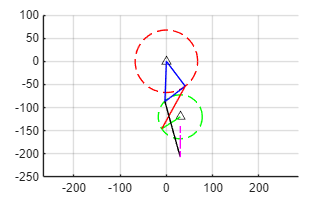


figure()

link_plot = deg2rad(0:5:360);

hold on
plot(O5x,O5y,"k^")
plot(O2x,O2y,"k^")

plot(subs(Cx,link_plot), subs(Cy,link_plot), "g--")
plot(subs(Ax,link_plot), subs(Ay,link_plot), "r--")
fanimator(h_link5)
fanimator(h_link2)
fanimator(h_link3)
fanimator(h_link4)

%plot(subs(Bx,link_plot), subs(By,link_plot), "k--")
plot(subs(Dx,link_plot), subs(Dy,link_plot), "m--")

grid on
hold off
axis equal

playAnimation

xlim("auto")
ylim("auto")

xlim("auto")
ylim("auto")


%% ========================================================================
%  PART 2: VELOCITY ANALYSIS (กำหนด omega = 1 rad/s)
% =========================================================================
disp('Performing Velocity Analysis...');

Performing Velocity Analysis...



% ★★★ กำหนดความเร็วรอบของ Driver (Link 5) ★★★
omega_driver = 1; % rad/s (ค่าคงที่)

% หลักการ: V = dP/dt = (dP/d_theta4) * (d_theta4/dt)
% ซึ่ง d_theta4/dt ก็คือ omega_driver นั่นเอง

% 1. ความเร็วเชิงมุมของ Link อื่นๆ (Angular Velocities)
% diff(..., theta4) คือการหาอนุพันธ์เทียบกับมุม driver
omega2_sym = diff(theta2_sol, theta4) * omega_driver; 
omega3_sym = diff(theta3_sol, theta4) * omega_driver;

% 2. ความเร็วเชิงเส้นของ Slider D (Linear Velocity of Slider)
VDy_sym = diff(Dy, theta4) * omega_driver;

%% ========================================================================
%  PART 3: PLOTTING RESULTS (สร้างกราฟความเร็วตลอด 360 องศา)
% =========================================================================
disp('Generating Velocity Graphs...');

Generating Velocity Graphs...


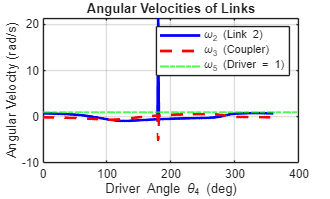


% แปลงสมการ Symbolic ให้เป็น Function Handle (เพื่อให้คำนวณเร็วขึ้น)
func_omega2 = matlabFunction(omega2_sym, 'Vars', theta4);
func_omega3 = matlabFunction(omega3_sym, 'Vars', theta4);
func_VDy    = matlabFunction(VDy_sym, 'Vars', theta4);

% สร้างช่วงมุมสำหรับพล็อตกราฟ (0 ถึง 360 องศา)
angle_range = deg2rad(0:1:360);

% คำนวณค่าความเร็วที่มุมต่างๆ
w2_vals = func_omega2(angle_range);
w3_vals = func_omega3(angle_range);
vD_vals = func_VDy(angle_range);

% --- กราฟที่ 1: ความเร็วเชิงมุม (Angular Velocities) ---
figure('Name', 'Angular Velocities');
plot(rad2deg(angle_range), w2_vals, 'b-', 'LineWidth', 2); hold on;
plot(rad2deg(angle_range), w3_vals, 'r--', 'LineWidth', 2);
yline(omega_driver, 'g-.', 'LineWidth', 1.5); % เส้นความเร็ว Driver (1 rad/s)
legend('\omega_2 (Link 2)', '\omega_3 (Coupler)', '\omega_5 (Driver = 1)');
xlabel('Driver Angle \theta_4 (deg)');
ylabel('Angular Velocity (rad/s)');
title('Angular Velocities of Links');
grid on;

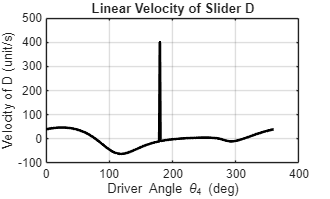


% --- กราฟที่ 2: ความเร็วสไลเดอร์ (Slider Velocity) ---
figure('Name', 'Slider Velocity');
plot(rad2deg(angle_range), vD_vals, 'k-', 'LineWidth', 2);
xlabel('Driver Angle \theta_4 (deg)');
ylabel('Velocity of D (unit/s)');
title('Linear Velocity of Slider D');
grid on;


% หาค่าความเร็วสูงสุดและต่ำสุดของสไลเดอร์
max_v = max(vD_vals);
min_v = min(vD_vals);
fprintf('Max Slider Velocity: %.2f unit/s\n', max_v);

Max Slider Velocity: 400.62 unit/s


fprintf('Min Slider Velocity: %.2f unit/s\n', min_v);

Min Slider Velocity: -62.05 unit/s
